Schnackenberg calculation

First calculation with a = 0.2 and b = 0.5 at g = 1000, d =100 with noise 1e-3

a = 0.2;
b = 0.5;
load('Datamedian2.mat')

[Schnack1m,modemode_case1] = median_mode(Schnack1m,Schnack1_median,'Maximal_mode',true,'max_mode',true);
[Schnack2m,modemode_case2] = median_mode(Schnack2m,Schnack2_median,'Maximal_mode',true,'max_mode',true);
[Schnack3m,modemode_case3] = median_mode(Schnack3m,Schnack3_median,'Maximal_mode',true,'max_mode',true);
[Schnack_2m,modemode_case_2] = median_mode(Schnack_2m,Schnack_2median,'Maximal_mode',true,'max_mode',true);
[Schnack_23m,modemode_case_23] = median_mode(Schnack_23m,Schnack_23median,'Maximal_mode',true,'max_mode',true);

[Schnack1m,modemode_case1] = median_mode(Schnack1m,Schnack1_median,'max_mode',true);
[Schnack2m,modemode_case2] = median_mode(Schnack2m,Schnack2_median,'max_mode',true);
[Schnack3m,modemode_case3] = median_mode(Schnack3m,Schnack3_median,'max_mode',true);
[Schnack_2m,modemode_case_2] = median_mode(Schnack_2m,Schnack_2median,'max_mode',true);
[Schnack_23m,modemode_case_23] = median_mode(Schnack_23m,Schnack_23median,'max_mode',true);

loglog_mode3(Schnack1_lin,'show_raster',2)

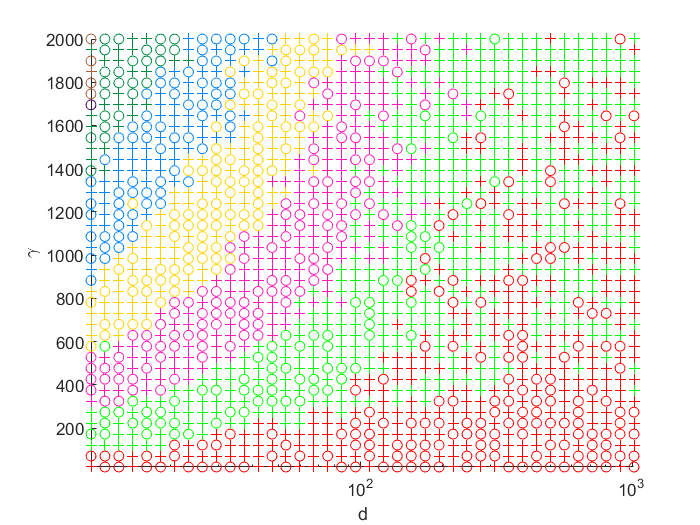

loglog_mode2(Schnack1m,'show_raster',0) 

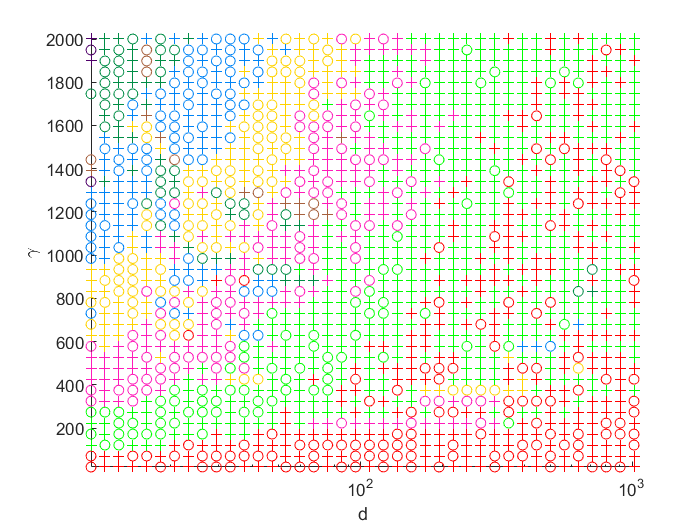

loglog_mode2(Schnack2m,'show_raster',0)

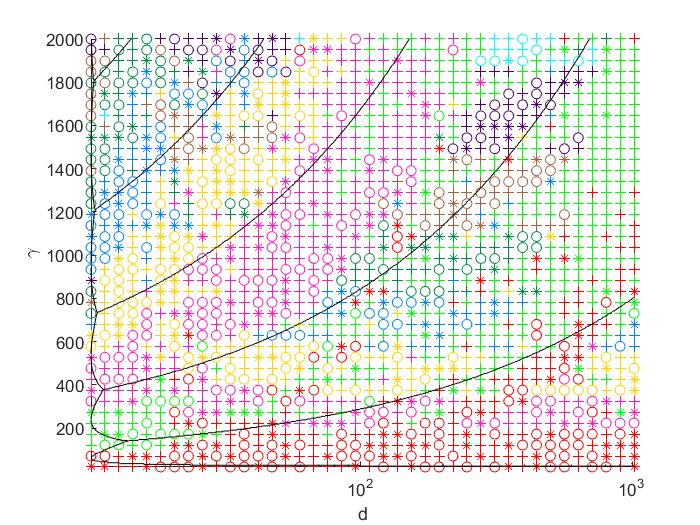

loglog_mode2(Schnack3m,'show_raster',2)

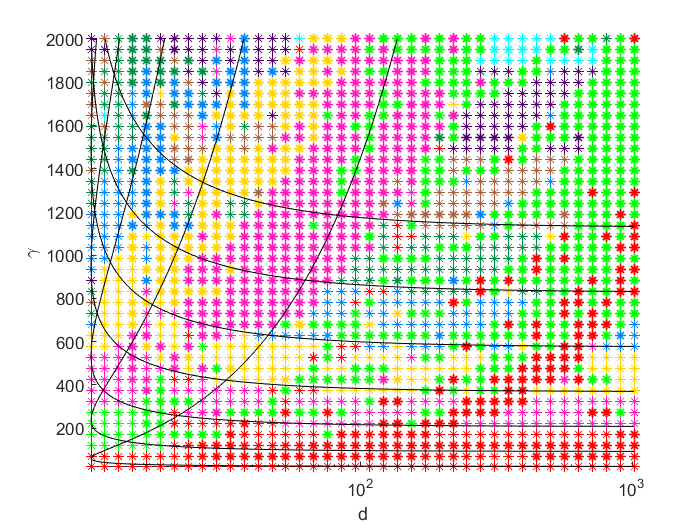


loglog_mode3(Schnack3m,'show_raster',1)

% loglog_mode3(Schnack2_lin,'show_raster',2)
% loglog_mode3(Schnack3_lin,'show',1)

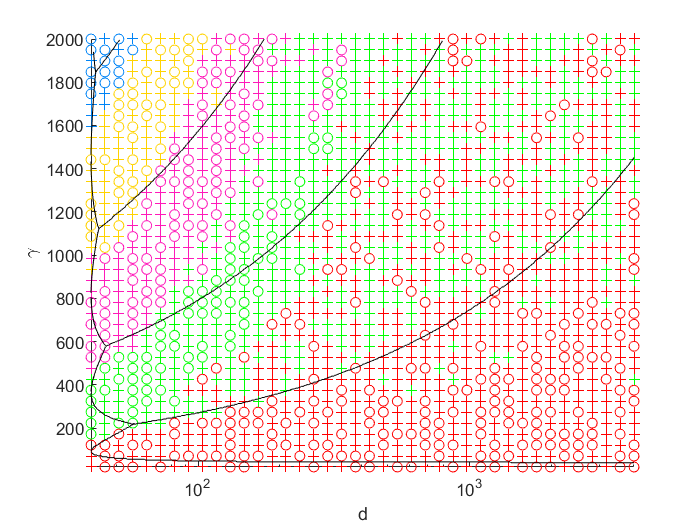

loglog_mode2(Schnack_2m,'show',2)

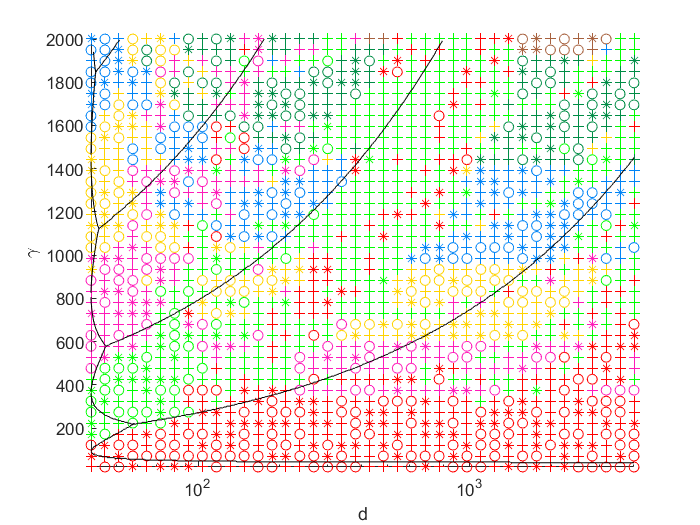

loglog_mode2(Schnack_23m,'show',2)

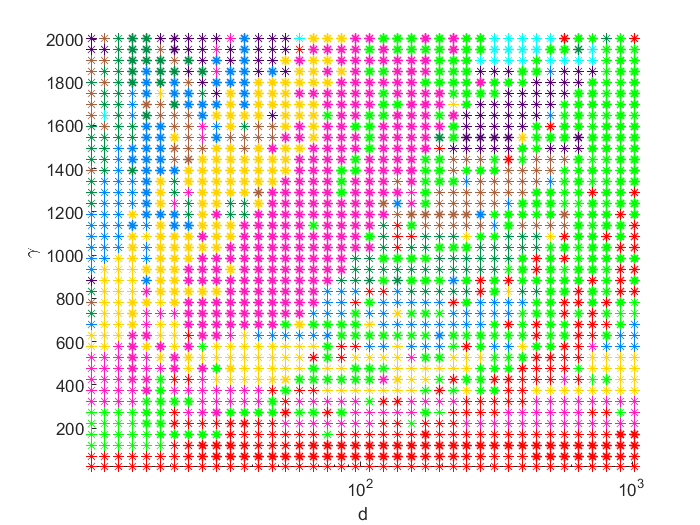

loglog_mode3(Schnack3m,'show_raster',0)

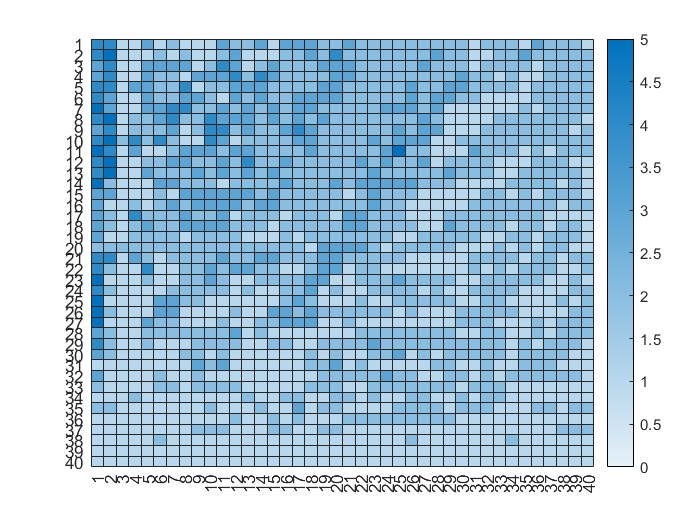

h3 =   HeatmapChart with properties:

        XData: {40×1 cell}
        YData: {40×1 cell}
    ColorData: [40×40 double]

  Show all properties


h3 = heatmap(flip(modemode_case3),'ColorLimits',[0 5])

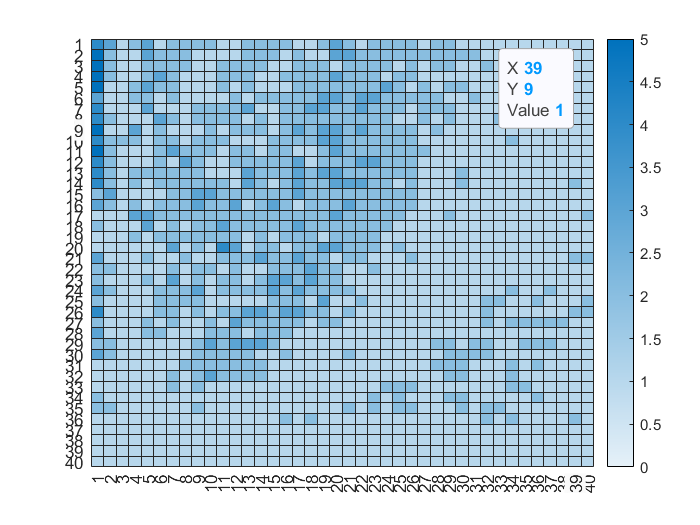

h2 =   HeatmapChart with properties:

        XData: {40×1 cell}
        YData: {40×1 cell}
    ColorData: [40×40 double]

  Show all properties


h2 = heatmap(flip(modemode_case2),'ColorLimits',[0 5])

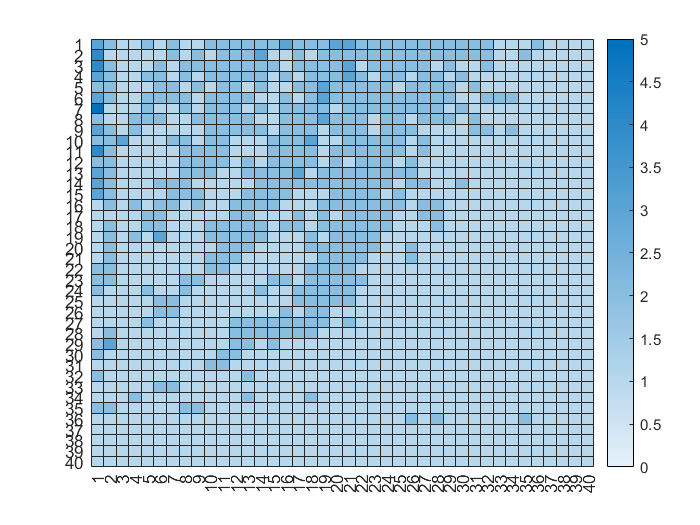

h1 =   HeatmapChart with properties:

        XData: {40×1 cell}
        YData: {40×1 cell}
    ColorData: [40×40 double]

  Show all properties


h1 = heatmap(flip(modemode_case1),'ColorLimits',[0 5])

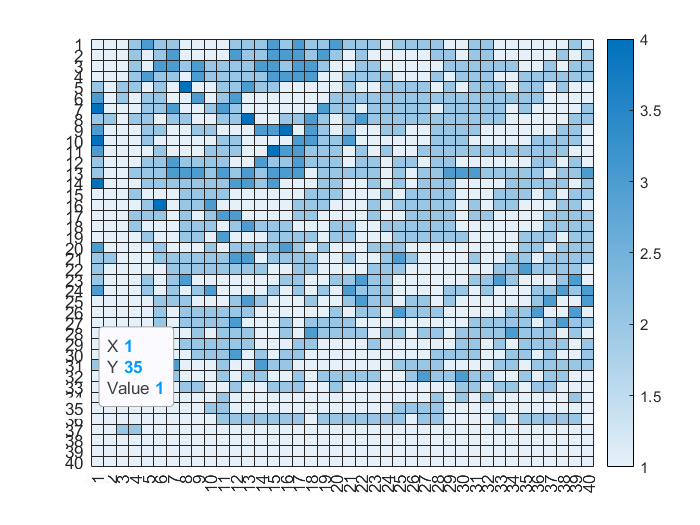

mtest = flip(modemode_case_23);
heatmap(mtest)

j_prom = logspace(-16,0,10);

Schnack1 = max_mode2(Schnack1,j_prom);
Schnack2 = max_mode2(Schnack2,j_prom);
Schnack3 = max_mode2(Schnack3,j_prom);
Schnack1 = max_mode2(Schnack1_lin,j_prom);
Schnack2 = max_mode2(Schnack2_lin,j_prom);
Schnack3 = max_mode2(Schnack3_lin,j_prom);

[Schnack_2.u1_mode,Schnack1lin_2.u2_mode] = max_mode(Schnack_2,j_prom);
[Schnack_2lin.u1_mode,Schnack_22lin.u2_mode] = max_mode(Schnack_2lin,j_prom);

figure;
predmodeSchnack = pred_mode(Schnack1,10)
figure;
predmodeSchnack2 = pred_mode(Schnack_2lin,10)

loglog_mode(Schnack1,'show_raster',0,'predmode',predmodeSchnack)
loadloglog_mode(Schnack2,'show_raster',0,'predmode',predmodeSchnack)
loglog_mode(Schnack3,'show_raster',0,'predmode',predmodeSchnack)
loglog_mode(Schnack1_lin,'show_raster',2,'predmode',predmodeSchnack)
loglog_mode(Schnack2_lin,'show_raster',2,'predmode',predmodeSchnack)
loglog_mode(Schnack3_lin,'show_raster',2,'predmode',predmodeSchnack)

loglog_mode(Schnack_2,'show',1)
loglog_mode(Schnack_2lin,'show',1)

 %gif_sol_time2(Schnack1.u1(:,end-4,:),Schnack1.j_d)

% figure;
% gif_sol_surv(Schnack1.u1,Schnack1.tspan)
% gif_sol_surv(Schnack1_lin.u1,Schnack2.tspan)
% gif_sol_surv(Schnack3.u1,Schnack3.tspan)

 jsm_d = linspace(3,12,40);
 jsm_g = linspace(50,1000,15);
 Schnacksmall = Sol_Schnack(a,b,jsm_d,jsm_g,1e-3);
 Schnacksmall_lin = Schnacksmall;


 tic
 [Schnacksmall.u1, Schnacksmall.u2] = Sol_Schnack_solv(Schnacksmall);
 toc

 tic
 [Schnacksmall_lin.u1, Schnacksmall_lin.u2] = Sol_Schnack_linsolv(Schnacksmall_lin);
 toc

%  j_prom = logspace(-16,0,10);
%  plot_gif_mode(Schnacksmall,j_prom,'show',1)
%  Sol_Schnack_gif_var(Schnacksmall,'d',-1)
%  
%  plot_gif_mode(Schnacksmall_lin,j_prom,'show',1)
%  Sol_Schnack_gif_var(Schnacksmall_lin,'d',-1)
% 
% 
